%==========================================================================
% Author:    N. Akhavan (UMich)
% Script:    rem_distribution_deciles_human_LW2min_DROP.m   (suggested name)
%
% Summary:
%   This script characterizes *where* REM occurs across the night by mapping each
%   subject's sleep episode onto a normalized time axis [0,1] and splitting it
%   into deciles (10 equal-duration segments).
%
% Data sources:
%   - Combined_BigResultTable.mat        (cycle-level summary: IREM, REMpost, etc.)
%   - Combined_BigStageDetailsTable.mat  (block-level Stage/Duration for LW filtering)
%
% Long-wake exclusion (cycle-level DROP):
%   For each REM cycle, if StageDetails contains ANY *single contiguous* Wake block
%   (Stage == WAKE_CODE, typically 5) with Duration ≥ WAKE_BREAK_MIN minutes
%   occurring within IREM, that entire cycle is excluded from analysis.
%
% Outputs (three complementary panels):
%   (1) PROXY / BOUT-BASED (REM ONSETS):
%       For each subject, count REM onsets per decile and convert to a fraction
%       of that subject's total nightly REM bouts. Plot mean ± SE across subjects.
%
%   (2) TIME-FRACTION (OVERLAP-SPLIT):
%       For each subject, compute how many seconds of REM fall *inside* each decile
%       by splitting each REM bout across deciles using interval overlap.
%       Convert to a fraction of that subject's total nightly REM time (REMpost).
%       Plot mean ± SE across subjects.
%
%   (3) ONSET-ASSIGNED REM AMOUNT (NO SPLITTING):
%       Assign the *entire* REMpost duration to the decile in which the REM bout
%       starts (REM onset). Report average REM minutes per decile (mean ± SE).
%
% Notes / interpretation:
%   - Panel (2) answers: "What fraction of total REM time is *spent* in each decile?"
%     (time is split across deciles when bouts cross boundaries)
%   - Panel (3) answers: "How much REM time is *initiated* in each decile?"
%     (full bout credited to its onset bin; no splitting)
%
% Change bins:
%   - Deciles are controlled by: decileEdges01 = linspace(0,1,11);  nDec = 10;
%     To use K bins, set decileEdges01 = linspace(0,1,K+1); nDec = K.
%
% Figures:
%   - Figure 1: mean fraction of nightly REM bouts by decile (proxy)
%   - Figure 2: mean fraction of nightly REM time by decile (overlap-split)
%   - Figure 3: mean REM minutes by onset decile (onset-assigned)
%
% Last updated: 2026-01-19
%==========================================================================

close all; clear; clc;


## Settings

combinedFolder  = 'C:\Users\naghm\OneDrive\Desktop\combined_out';
matR            = fullfile(combinedFolder,'Combined_BigResultTable.mat');
matD            = fullfile(combinedFolder,'Combined_BigStageDetailsTable.mat');

WAKE_BREAK_MIN  = 2;
WAKE_BREAK_SEC  = WAKE_BREAK_MIN * 60;   % 120 s

SAVE_FIG   = false;   % set true if you want PNGs
outPng_proxy = fullfile(combinedFolder,'tables_out', ...
                 sprintf('Fig_REM_deciles_proxy_longwake%g.png', WAKE_BREAK_MIN));
outPng_time  = fullfile(combinedFolder,'tables_out', ...
                 sprintf('Fig_REM_deciles_time_longwake%g.png', WAKE_BREAK_MIN));

% 10 segments (deciles) on [0,1]
decileEdges01 = linspace(0,1,11);
decileMidsPct = 100 * (decileEdges01(1:end-1) + decileEdges01(2:end))/2;
nDec = 10;


## Load

assert(isfile(matR), 'Missing %s', matR);
assert(isfile(matD), 'Missing %s', matD);
SR = load(matR);  R = SR.Combined_BigResultTable;
SD = load(matD);  D = SD.Combined_BigStageDetailsTable;

%% Normalize types
R.Subject_Index   = string(R.Subject_Index);
if ~ismember("REM_Cycle_Index", string(R.Properties.VariableNames))
    R.REM_Cycle_Index = strings(height(R),1);
end
R.REM_Cycle_Index = string(R.REM_Cycle_Index);

needR = ["IREM","NREM","Wake","Movement"];
for v = needR
    if ~ismember(v, string(R.Properties.VariableNames)), R.(v) = NaN(height(R),1); end
    R.(v) = double(R.(v));
end
if (~ismember("IREM", string(R.Properties.VariableNames))) || all(isnan(R.IREM))
    if all(ismember(["NREM","Wake","Movement"], string(R.Properties.VariableNames)))
        R.IREM = double(R.NREM) + double(R.Wake) + double(R.Movement);
    else
        error('Cannot reconstruct IREM: missing NREM/Wake/Movement.');
    end
else
    R.IREM = double(R.IREM);
end

% Stage details table D
if ~ismember("Stage",    string(D.Properties.VariableNames)), error('Stage column not found in stage table.'); end
if ~ismember("Duration", string(D.Properties.VariableNames)), error('Duration column not found in stage table.'); end
if ~ismember("REM_Cycle_Index", string(D.Properties.VariableNames)), error('Stage table missing REM_Cycle_Index.'); end
D.Stage           = double(D.Stage);
D.Duration        = double(D.Duration);
D.REM_Cycle_Index = string(D.REM_Cycle_Index);


## Long-wake DROP

WAKE_CODE = 5;   % adjust if your Wake label is different

if ~ismember("ord", string(D.Properties.VariableNames))
    D.ord = (1:height(D))';
end
D = sortrows(D, {'REM_Cycle_Index','ord'});

[Gd, keys]   = findgroups(D.REM_Cycle_Index);
hasLongWake  = false(numel(keys),1);
for gi = 1:numel(keys)
    rows = find(Gd==gi);
    st   = D.Stage(rows);
    du   = D.Duration(rows);
    if any(isfinite(st) & isfinite(du) & (st==WAKE_CODE) & (du >= WAKE_BREAK_SEC))
        hasLongWake(gi) = true;
    end
end

FlagTab = table(keys, hasLongWake, 'VariableNames',{'REM_Cycle_Index','HasLongWake'});
R = outerjoin(R, FlagTab, 'Keys','REM_Cycle_Index', 'MergeKeys',true, 'Type','left');

if ~ismember("HasLongWake", string(R.Properties.VariableNames))
    R.HasLongWake = false(height(R),1);
else
    R.HasLongWake = logical(fillmissing(double(R.HasLongWake), 'constant', 0));
end

maskDrop = (R.HasLongWake == 1);
nDrop    = sum(maskDrop);
Rkeep    = R(~maskDrop, :);
fprintf('Long-wake DROP: Wake >= %d min (>= %d s) — dropped %d cycles; kept %d.\n', ...
        WAKE_BREAK_MIN, WAKE_BREAK_SEC, nDrop, height(Rkeep));

Long-wake DROP: Wake >= 2 min (>= 120 s) — dropped 1028 cycles; kept 3994.



%% Common setup
% We'll use IREM for both plots; plus REMpost for the time-based plot
if ~ismember("REMpost", string(Rkeep.Properties.VariableNames))
    error('Combined_BigResultTable missing REMpost column (needed for REM time plot).');
end
Rkeep.IREM    = double(Rkeep.IREM);
Rkeep.REMpost = double(Rkeep.REMpost);



## PLOT: REM onset distribution (fraction of nightly bouts)

valid_proxy = isfinite(Rkeep.IREM) & (Rkeep.IREM >= 0);

rec = string(Rkeep.Subject_Index);
[G, recNames] = findgroups(rec);
REMfrac_bouts = NaN(numel(recNames), nDec);    % per-subject fractions (bouts)

for gi = 1:numel(recNames)
    idxAll = find(G==gi);
    idx    = idxAll(valid_proxy(idxAll));
    if isempty(idx), continue; end

    IREM_sec = Rkeep.IREM(idx);
    IREM_sec(~isfinite(IREM_sec)) = 0;

    % treat cycle duration as just IREM
    cycDur  = IREM_sec;
    sCum    = [0; cumsum(cycDur)];
    totalNight = sCum(end);
    if totalNight <= 0, continue; end

    decAbs = decileEdges01 * totalNight;

    % REM onsets at end of IREM
    REM_onsets = sCum(1:end-1) + IREM_sec;
    ok = isfinite(REM_onsets); REM_onsets = REM_onsets(ok);
    if isempty(REM_onsets), continue; end

    binID  = discretize(REM_onsets, decAbs);
    counts = accumarray(binID(~isnan(binID)), 1, [nDec,1], @sum, 0);

    totBouts = sum(counts);
    if totBouts > 0
        REMfrac_bouts(gi,:) = (counts(:) / totBouts).';
    end
end

keepRows = any(isfinite(REMfrac_bouts), 2);
REMfrac_bouts = REMfrac_bouts(keepRows, :);
if isempty(REMfrac_bouts)
    error('No subjects with computable REM onset fractions after LW=2 min drop.');
end

mREM_proxy = mean(REMfrac_bouts, 1, 'omitnan');
sREM_proxy = std(REMfrac_bouts, 0, 1, 'omitnan');
nSubj_proxy = size(REMfrac_bouts, 1);
seREM_proxy = sREM_proxy / max(1, sqrt(nSubj_proxy));


## Plot 1: REM onset distribution

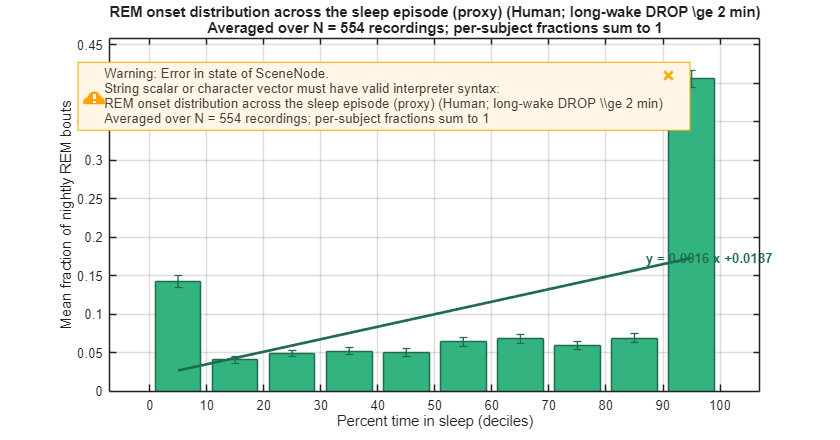

figure('Color','w','Position',[100 100 840 440]);
face = [0.20 0.70 0.50]; edge = face*0.6;   % teal theme
bar(decileMidsPct, mREM_proxy, 'FaceColor', face, 'EdgeColor', edge); hold on;
errorbar(decileMidsPct, mREM_proxy, seREM_proxy, 'LineStyle','none', ...
         'Color', edge, 'LineWidth', 1);

xlabel('Percent time in sleep (deciles)');
ylabel('Mean fraction of nightly REM bouts');
title({sprintf('REM onset distribution across the sleep episode (proxy) (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Averaged over N = %d recordings; per-subject fractions sum to 1', nSubj_proxy)});

ylim([0, max(0.001, 1.1*max(mREM_proxy+seREM_proxy))]);
grid on; box on;

% Linear fit
p1 = polyfit(decileMidsPct, mREM_proxy, 1);
yfit1 = polyval(p1, decileMidsPct);
plot(decileMidsPct, yfit1, '-', 'LineWidth', 2, 'Color', edge);
eqnStr1 = sprintf('y = %.4f x %+ .4f', p1(1), p1(2));
text(decileMidsPct(end)-8, yfit1(end), eqnStr1, 'Color', edge, ...
     'FontSize',10, 'FontWeight','bold');


if SAVE_FIG
    outDir = fileparts(outPng_proxy);
    if ~isfolder(outDir), mkdir(outDir); end
    exportgraphics(gcf, outPng_proxy, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng_proxy);
end



## 2) REM time distribution (fraction of nightly REM time)

%    Uses REMpost duration for each REM bout
valid_time = isfinite(Rkeep.IREM) & (Rkeep.IREM >= 0) & ...
             isfinite(Rkeep.REMpost) & (Rkeep.REMpost > 0);

rec2 = string(Rkeep.Subject_Index);
[G2, recNames2] = findgroups(rec2);
REMfrac_time = NaN(numel(recNames2), nDec);    % per-subject fractions (time)

for gi = 1:numel(recNames2)
    idxAll = find(G2==gi);
    idx    = idxAll(valid_time(idxAll));
    if isempty(idx), continue; end

    IREM_sec    = Rkeep.IREM(idx);
    REMpost_sec = Rkeep.REMpost(idx);

    IREM_sec(~isfinite(IREM_sec))       = 0;
    REMpost_sec(~isfinite(REMpost_sec)) = 0;

    % Full cycle duration = IREM + REM bout
    cycDur  = IREM_sec + REMpost_sec;
    sCum    = [0; cumsum(cycDur)];
    totalNight = sCum(end);
    if totalNight <= 0, continue; end

    decAbs = decileEdges01 * totalNight;

    % For each REM bout, compute overlap of [REM_start, REM_end] with deciles
    remPerDecile = zeros(nDec,1);
    for c = 1:numel(REMpost_sec)
        a = sCum(c) + IREM_sec(c);            % REM start
        b = a + REMpost_sec(c);               % REM end
        if ~(isfinite(a) && isfinite(b) && b>a), continue; end
        for d = 1:nDec
            L = overlap_len(a, b, decAbs(d), decAbs(d+1));
            if L > 0
                remPerDecile(d) = remPerDecile(d) + L;
            end
        end
    end

    totREM = sum(REMpost_sec(isfinite(REMpost_sec)));
    if totREM > 0
        REMfrac_time(gi,:) = (remPerDecile(:) / totREM).';
    end
end

keepRowsT = any(isfinite(REMfrac_time), 2);
REMfrac_time = REMfrac_time(keepRowsT, :);
if isempty(REMfrac_time)
    error('No subjects with computable REM time fractions after LW=2 min drop.');
end

mREM_time   = mean(REMfrac_time, 1, 'omitnan');
sREM_time   = std(REMfrac_time, 0, 1, 'omitnan');
nSubj_time  = size(REMfrac_time, 1);
seREM_time  = sREM_time / max(1, sqrt(nSubj_time));


## Plot 2: REM time distribution

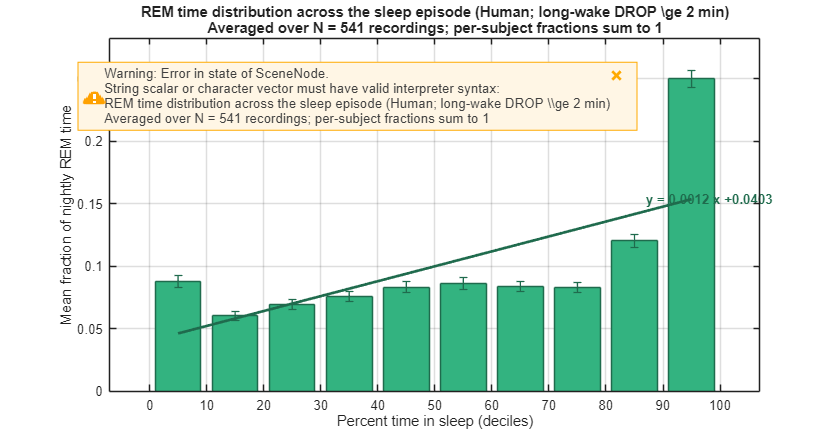

figure('Color','w','Position',[120 120 840 440]);
faceT = [0.20 0.70 0.50]; edgeT = faceT*0.6;
bar(decileMidsPct, mREM_time, 'FaceColor', faceT, 'EdgeColor', edgeT); hold on;
errorbar(decileMidsPct, mREM_time, seREM_time, 'LineStyle','none', ...
         'Color', edgeT, 'LineWidth', 1);

xlabel('Percent time in sleep (deciles)');
ylabel('Mean fraction of nightly REM time');
title({sprintf('REM time distribution across the sleep episode (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Averaged over N = %d recordings; per-subject fractions sum to 1', nSubj_time)});

ylim([0, max(0.001, 1.1*max(mREM_time+seREM_time))]);
grid on; box on;

% Linear fit
p2 = polyfit(decileMidsPct, mREM_time, 1);
yfit2 = polyval(p2, decileMidsPct);
plot(decileMidsPct, yfit2, '-', 'LineWidth', 2, 'Color', edgeT);
eqnStr2 = sprintf('y = %.4f x %+ .4f', p2(1), p2(2));
text(decileMidsPct(end)-8, yfit2(end), eqnStr2, 'Color', edgeT, ...
     'FontSize',10, 'FontWeight','bold');


if SAVE_FIG
    outDir = fileparts(outPng_time);
    if ~isfolder(outDir), mkdir(outDir); end
    exportgraphics(gcf, outPng_time, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng_time);
end




## 3) ONSET-ASSIGNED REM AMOUNT (MINUTES): assign FULL REMpost to the decile where REM starts

% Output: average REM minutes per decile (mean ± SE across subjects)

valid_onset = isfinite(Rkeep.IREM) & (Rkeep.IREM >= 0) & ...
              isfinite(Rkeep.REMpost) & (Rkeep.REMpost > 0);

rec3 = string(Rkeep.Subject_Index);
[G3, recNames3] = findgroups(rec3);

REMamt_time_onset = NaN(numel(recNames3), nDec);   % per-subject REM MINUTES per decile

for gi = 1:numel(recNames3)
    idxAll = find(G3==gi);
    idx    = idxAll(valid_onset(idxAll));
    if isempty(idx), continue; end

    IREM_sec    = double(Rkeep.IREM(idx));
    REMpost_sec = double(Rkeep.REMpost(idx));

    IREM_sec(~isfinite(IREM_sec))       = 0;
    REMpost_sec(~isfinite(REMpost_sec)) = 0;

    % Define deciles using full cycle duration = IREM + REMpost  (still in seconds)
    cycDur  = IREM_sec + REMpost_sec;
    sCum    = [0; cumsum(cycDur)];
    totalNight = sCum(end);
    if totalNight <= 0, continue; end

    decAbs = decileEdges01 * totalNight;

    % Onset times (seconds from start)
    REM_onsets = sCum(1:end-1) + IREM_sec;

    % Decile ID for each onset
    binID = discretize(REM_onsets, decAbs);   % 1..nDec or NaN

    ok = ~isnan(binID) & isfinite(binID) & isfinite(REMpost_sec) & (REMpost_sec > 0);
    binID = binID(ok);

    dur_min = (REMpost_sec(ok)) / 60;         % convert to MINUTES here

    % Assign FULL duration (minutes) to onset decile
    remPerDecile_onset = accumarray(binID, dur_min, [nDec, 1], @sum, 0);

    % Store this subject's REM minutes per decile
    REMamt_time_onset(gi,:) = remPerDecile_onset(:).';
end

% Keep subjects with any data
keepA = any(isfinite(REMamt_time_onset), 2);
REMamt_time_onset = REMamt_time_onset(keepA, :);
nSubj_onsetA = size(REMamt_time_onset, 1);

if isempty(REMamt_time_onset)
    error('No subjects with computable onset-assigned REM amounts after LW=2 min drop.');
end

m_onsetA  = mean(REMamt_time_onset, 1, 'omitnan');  % minutes
se_onsetA = std(REMamt_time_onset, 0, 1, 'omitnan') / max(1, sqrt(nSubj_onsetA));


## Plot: onset-assigned REM time amount (minutes)

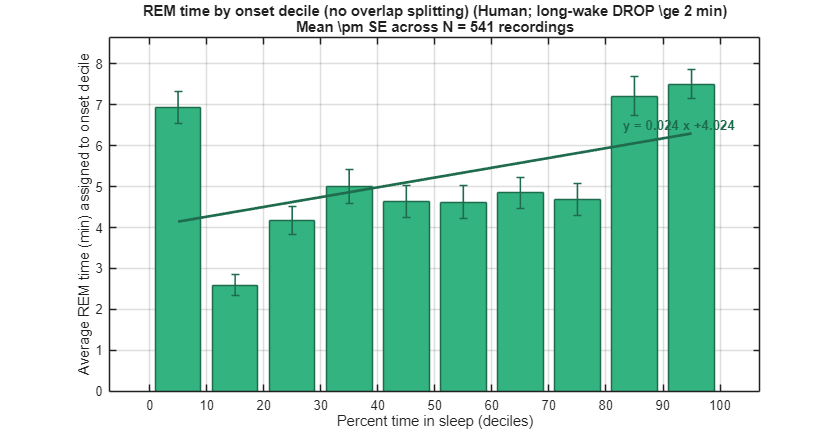

figure('Color','w','Position',[160 160 840 440]);
faceO = [0.20 0.70 0.50]; edgeO = faceO*0.6;

bar(decileMidsPct, m_onsetA, 'FaceColor', faceO, 'EdgeColor', edgeO); hold on;
errorbar(decileMidsPct, m_onsetA, se_onsetA, 'LineStyle','none', ...
         'Color', edgeO, 'LineWidth', 1.2);

xlabel('Percent time in sleep (deciles)');
ylabel('Average REM time (min) assigned to onset decile');
title({sprintf('REM time by onset decile (no overlap splitting) (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Mean \\pm SE across N = %d recordings', nSubj_onsetA)}, 'Interpreter','none');

grid on; box on;
ylim([0, max(0.01, 1.1*max(m_onsetA + se_onsetA))]);

% Linear regression on decile means (minutes vs percent)
p3 = polyfit(decileMidsPct, m_onsetA, 1);
yfit3 = polyval(p3, decileMidsPct);
plot(decileMidsPct, yfit3, '-', 'LineWidth', 2, 'Color', edgeO);
% Linear regression on decile means (minutes vs percent)
p3 = polyfit(decileMidsPct, m_onsetA, 1);   % y = a x + b
yfit3 = polyval(p3, decileMidsPct);
plot(decileMidsPct, yfit3, '-', 'LineWidth', 2, 'Color', edgeO);

% ----- Equation text on plot -----
eqnStr = sprintf('y = %.3f x %+ .3f', p3(1), p3(2));
xpos = decileMidsPct(end) - 12;   % adjust if needed
ypos = yfit3(end);
text(xpos, ypos, eqnStr, ...
     'Color', edgeO, ...
     'FontSize', 10, ...
     'FontWeight','bold', ...
     'HorizontalAlignment','left', ...
     'VerticalAlignment','bottom');

## Function

function L = overlap_len(a1, a2, b1, b2)
% Length of overlap between [a1,a2] and [b1,b2]
if ~(isfinite(a1)&&isfinite(a2)&&isfinite(b1)&&isfinite(b2)), L = 0; return; end
if a2 <= a1 || b2 <= b1, L = 0; return; end
L = max(0, min(a2,b2) - max(a1,b1));
end
